# **TP2 de Méthodes de Signal Avancées Soustraction Adaptative de Bruit**

clc; 
clear all ;

####                                         I. PARTIE 1

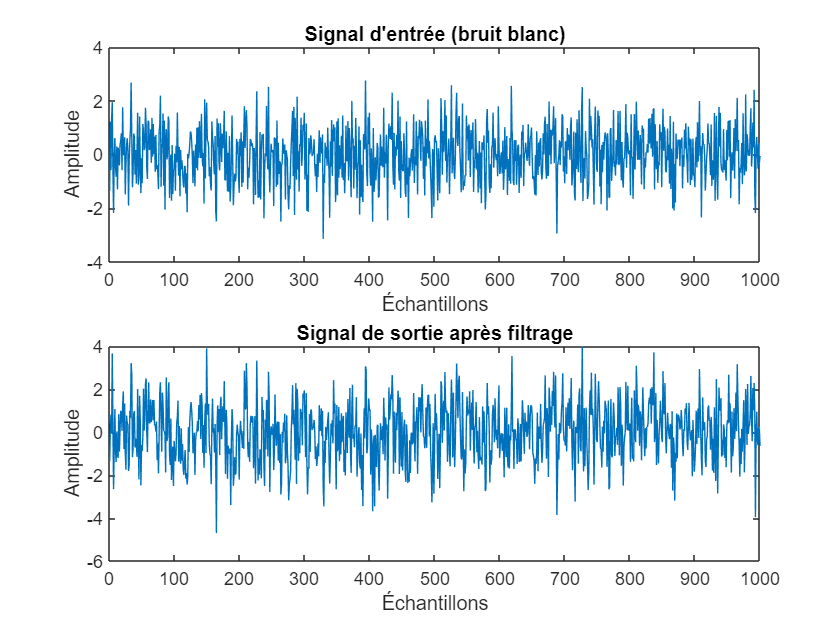

N = 1000;  % Number of samples
x = randn(N, 1);  % White noise
h = [1; 0.8; -0.3; 0.4];  % Impulse response of filter
d = filter(h, 1, x);  % Output signal

figure;
subplot(2, 1, 1);
plot(x);
title('Signal d''entrée (bruit blanc)');
xlabel('Échantillons');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(d);
title('Signal de sortie après filtrage');
xlabel('Échantillons');
ylabel('Amplitude');

#### 3- Validation de l’algorithme RLS.

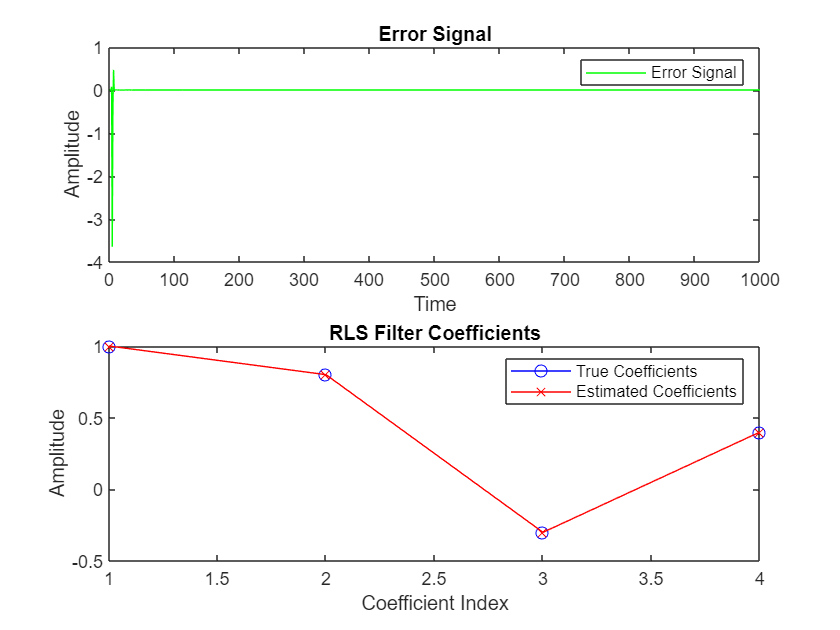

P = 4;  % Filter order
lambda = 0.99;
delta  = 0.01;
[w, y, e] = Algo_RLS(x, d, P, lambda, delta);

figure;
subplot(2, 1, 1);
plot(x);
plot(1:N, e, 'g');
legend('Error Signal');
xlabel('Time'); ylabel('Amplitude'); 
title('Error Signal');

subplot(2, 1, 2);
plot(1:P, h, 'bo-', 1:P, w(:, end), 'rx-');
legend('True Coefficients', 'Estimated Coefficients');
xlabel('Coefficient Index'); ylabel('Amplitude'); 
title('RLS Filter Coefficients');

####  4- Test de l’algorithme RLS avec un signal simulé.

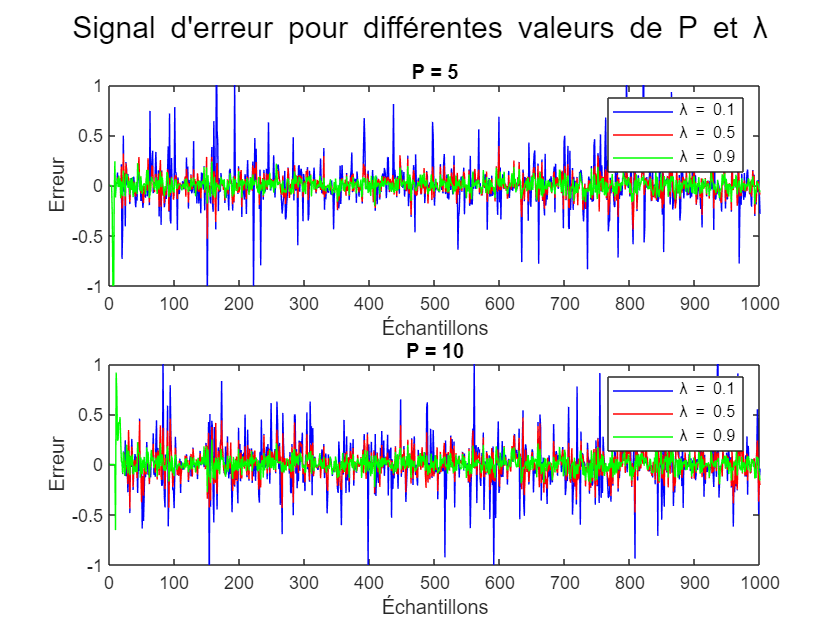

% Paramètres de simulation
noise = 0.06 * randn(N, 1); % Bruit ajouté

% Définition des paramètres
delta1 = 0.01;             % Petite constante pour initialiser P_inv
P_values = [5, 10];        % Différentes valeurs pour la longueur du filtre
lambda_values = [0.1, 0.5, 0.9]; % Différentes valeurs de lambda

% Création de la figure pour afficher les résultats
figure;

% Boucle sur les valeurs de P
for P_idx = 1:length(P_values)
    P = P_values(P_idx);

    % Création du filtre FIR pour la longueur P et génération du signal désiré
    h = fir1(P - 1, 0.5);
    d = filter(h, 1, x) + noise;  % Signal de sortie désiré avec bruit ajouté

    % Initialisation d'une matrice pour stocker les signaux d'erreur
    errors = zeros(N, length(lambda_values));

    % Boucle sur les valeurs de lambda
    for lambda_idx = 1:length(lambda_values)
        lambda = lambda_values(lambda_idx);

        % Application de l'algorithme RLS pour chaque combinaison (P, lambda)
        [~, ~, e] = Algo_RLS(x, d, P, lambda, delta1);

        % Stockage du signal d'erreur pour affichage
        errors(:, lambda_idx) = e;
    end

    % Affichage des résultats pour chaque P dans une sous-figure
    subplot(2, 1, P_idx);
    plot(1:N, errors(:, 1), 'b', 1:N, errors(:, 2), 'r', 1:N, errors(:, 3), 'g');
    ylim([-1, 1]); % Fixe l'échelle de l'axe y entre -1 et 1

    % Légende et titre
    legend('\lambda = 0.1', '\lambda = 0.5', '\lambda = 0.9');
    title(['P = ', num2str(P)]);
    xlabel('Échantillons');
    ylabel('Erreur');
end

% Titre global pour la figure
sgtitle('Signal d''erreur pour différentes valeurs de P et \lambda');

####                                         II. PARTIE 2

% Charger le signal vocal
[s, Fs] = audioread('C:\Users\Abdelhamied\Desktop\ENSEA\MATLAB\SA\TP2\Sources\Voix1.wav');

warning('off', 'all');  % Turn off all warnings
t = (0:length(s)-1)/Fs;

N = 85000

N = 85000

N1 = 0.05*randn(N, 1);
h = fir1(32, 0.5);
N0 = filter(h, 1, N1);
s_noised = s + N0;

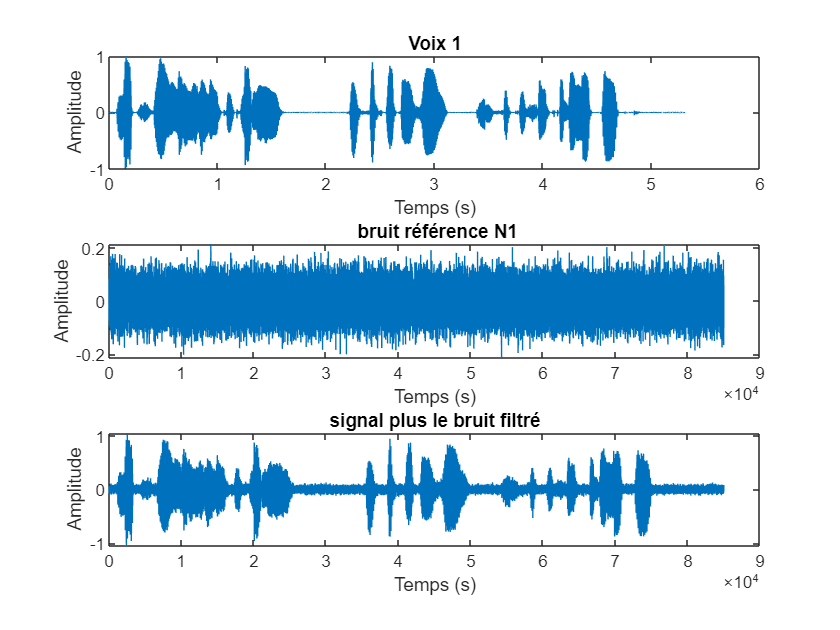

figure;
subplot(3, 1, 1);
plot(t,s);
title('Voix 1');
xlabel('Temps (s)');
ylabel('Amplitude');;

subplot(3, 1, 2);
plot(N1);
title(' bruit référence N1');
xlabel('Temps (s)');
ylabel('Amplitude');

subplot(3, 1, 3);
plot(s_noised);
title('signal plus le bruit filtré');
xlabel('Temps (s)');
ylabel('Amplitude');

[~, s_estim, e] = Algo_RLS(s_noised, s, 5, 0.99, 0.01);

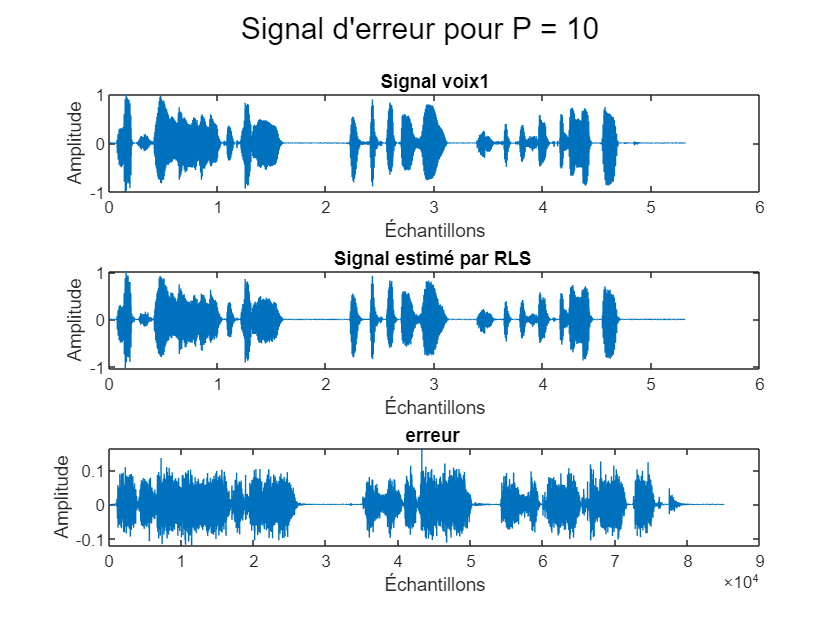

figure;
subplot(3, 1, 1);
plot(t,s);
title('Signal voix1');
xlabel('Échantillons');
ylabel('Amplitude');

subplot(3, 1, 2);
plot(t,s_estim);
title('Signal estimé par RLS ');
xlabel('Échantillons');
ylabel('Amplitude');

subplot(3, 1, 3);
plot(e);
title('erreur ');
xlabel('Échantillons');
ylabel('Amplitude');

sound(s, Fs);

####                                         III. PARTIE 3

#### 3) Test de l’algorithme NLMS avec un signal simulé.

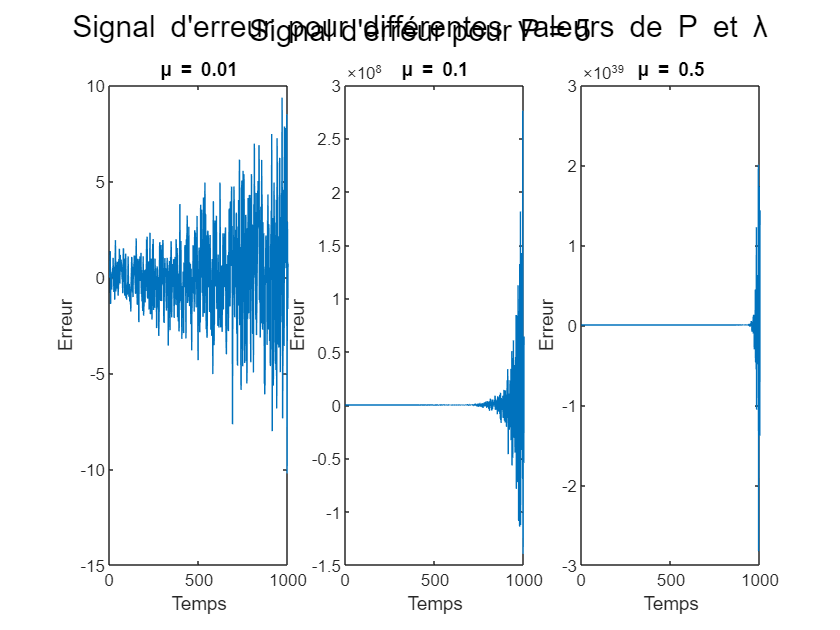

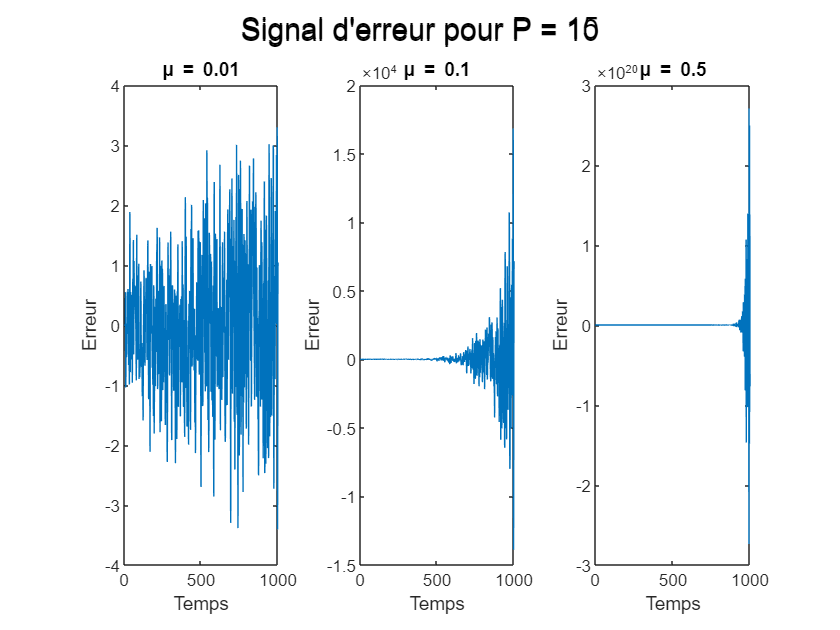

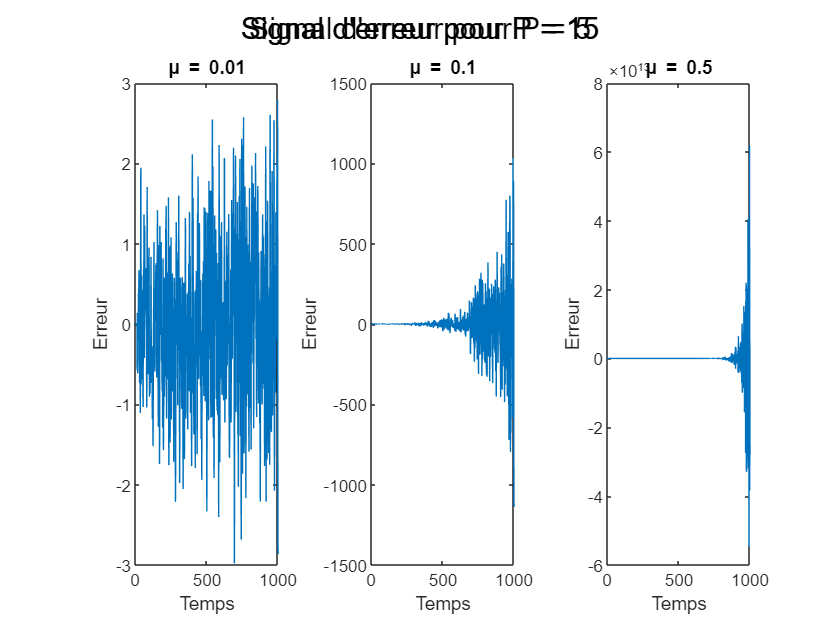

% Paramètres de simulation
N = 1000;
noise = 0.05 * randn(N, 1); % Bruit ajouté

% Différentes valeurs pour la longueur du filtre
P_values = [5, 10, 15];
mu_values = [0.01, 0.1, 0.5]; % Valeurs du pas d'apprentissage

% Boucle pour tester différentes longueurs de filtre et valeurs de mu
for P_idx = 1:length(P_values)
    P = P_values(P_idx);

    % Création du filtre pour la longueur P avec fréquence de coupure 0.5
    h = fir1(P - 1, 0.5);

    % Génération du signal de sortie désiré avec le bruit ajouté
    d = filter(h, 1, x);
    d_noisy = d + noise;

    figure; % Crée une nouvelle figure pour chaque longueur de filtre P

    % Boucle sur les valeurs de mu
    for mu_idx = 1:length(mu_values)
        mu = mu_values(mu_idx);

        % Application de l'algorithme LMS
        [w, y, e] = Algo_NLMS(x, d_noisy, P, mu);

        % Sous-figure pour chaque valeur de mu
        subplot(1, length(mu_values), mu_idx);
        plot(1:N, e);

        % Paramètres des sous-figures
        title(['\mu = ', num2str(mu)]);
        xlabel('Temps'); ylabel('Erreur');
    end

    % Titre global pour la figure
    sgtitle(['Signal d''erreur pour P = ', num2str(P)]);
end